clear;
clc

filename = "CalibrationData/Chip2_102400_LowSpeed.mat"

filename = "CalibrationData/Chip2_102400_LowSpeed.mat"

load(filename)


### Gain Calculation and Identification

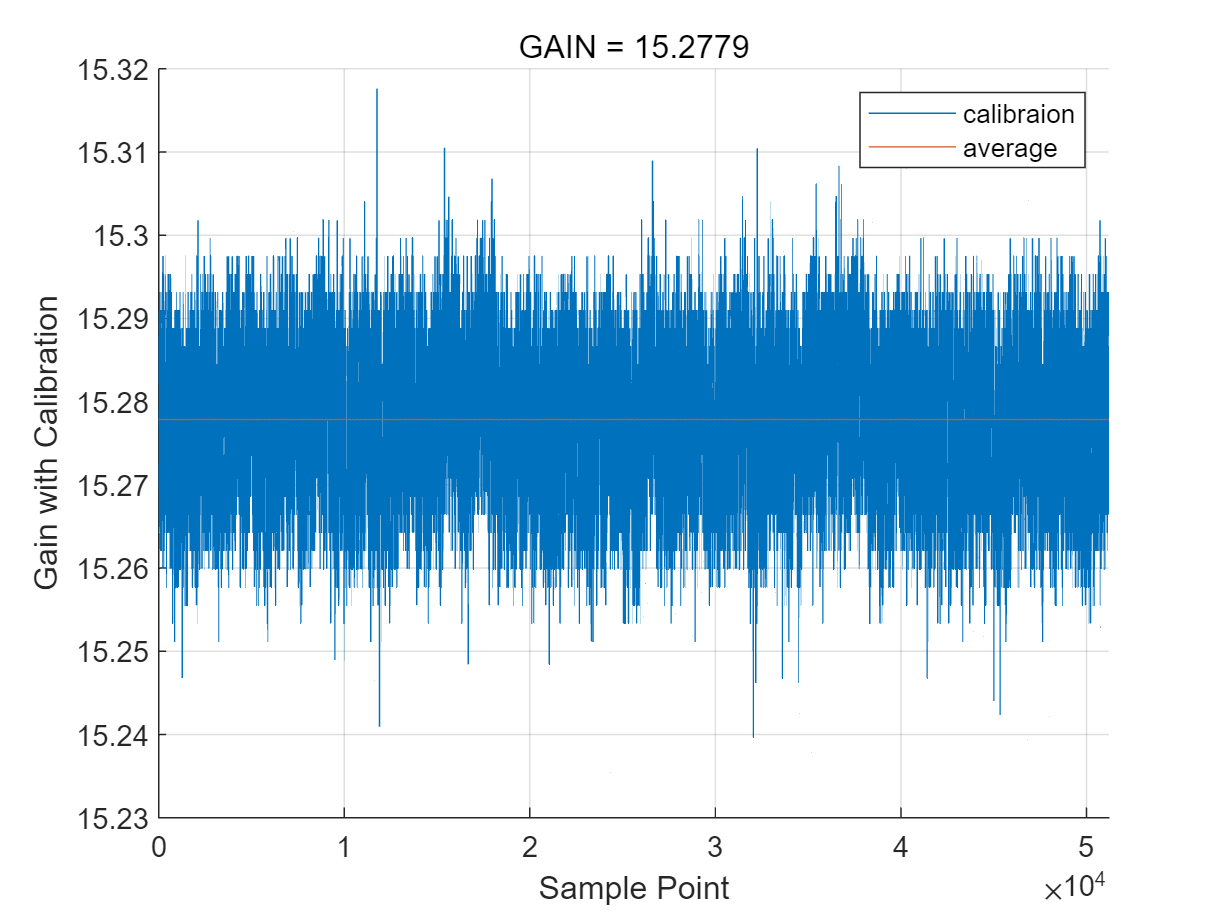

Gain_list =    15.2736
   15.2845
   15.2664
   15.2801
   15.2758
   15.2823
   15.2801
   15.2910
   15.2823
   15.2823


Gain = 15.2779

[Gain_list, Gain] = deltaGain(data_N4_calib(:, 2:end), 10, 'on')


Vout_N4 = data_N4 .* (1.8 / 2^5);

[sinad_cb, thd_cb, Vout] = Calib_Gain_seq(Vout_N4, Gain);


### Gain Average Effect

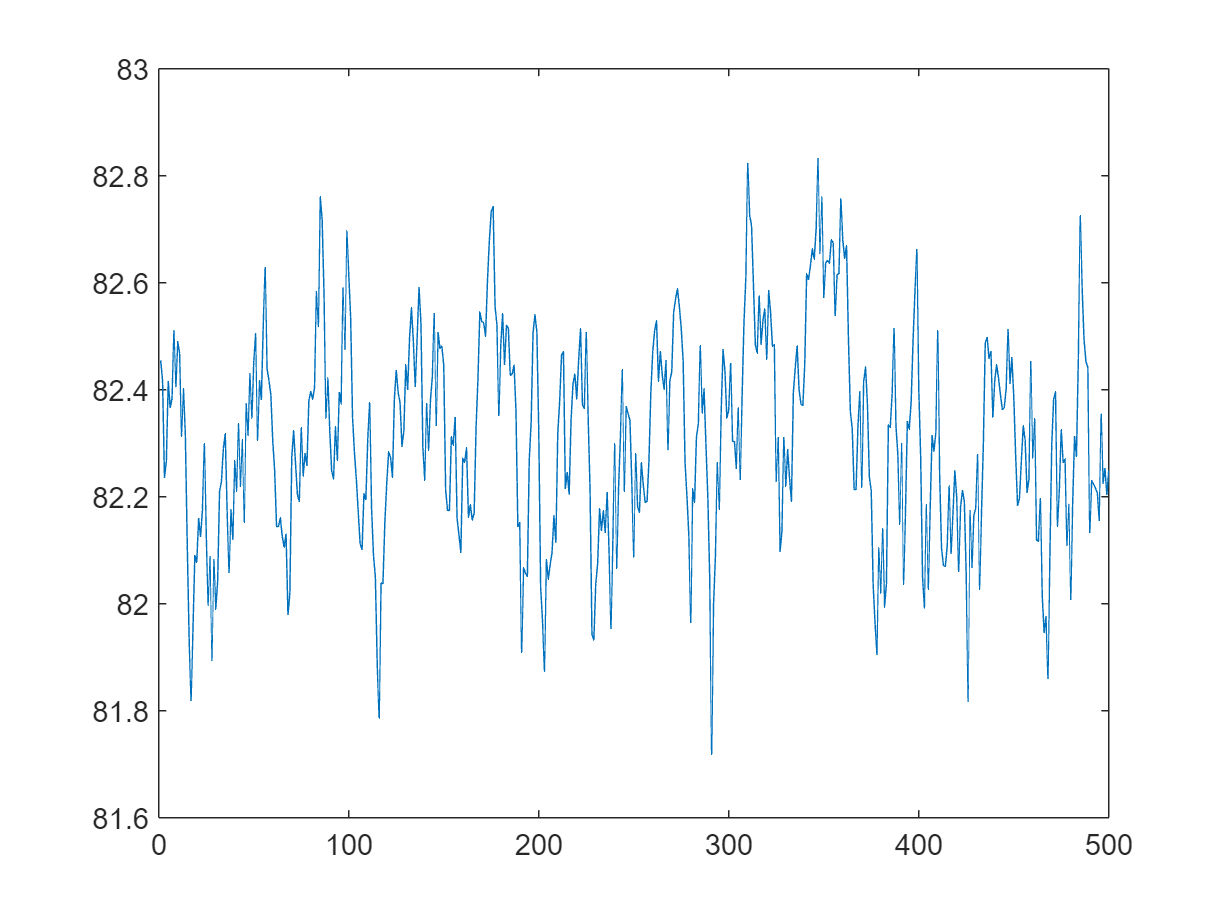

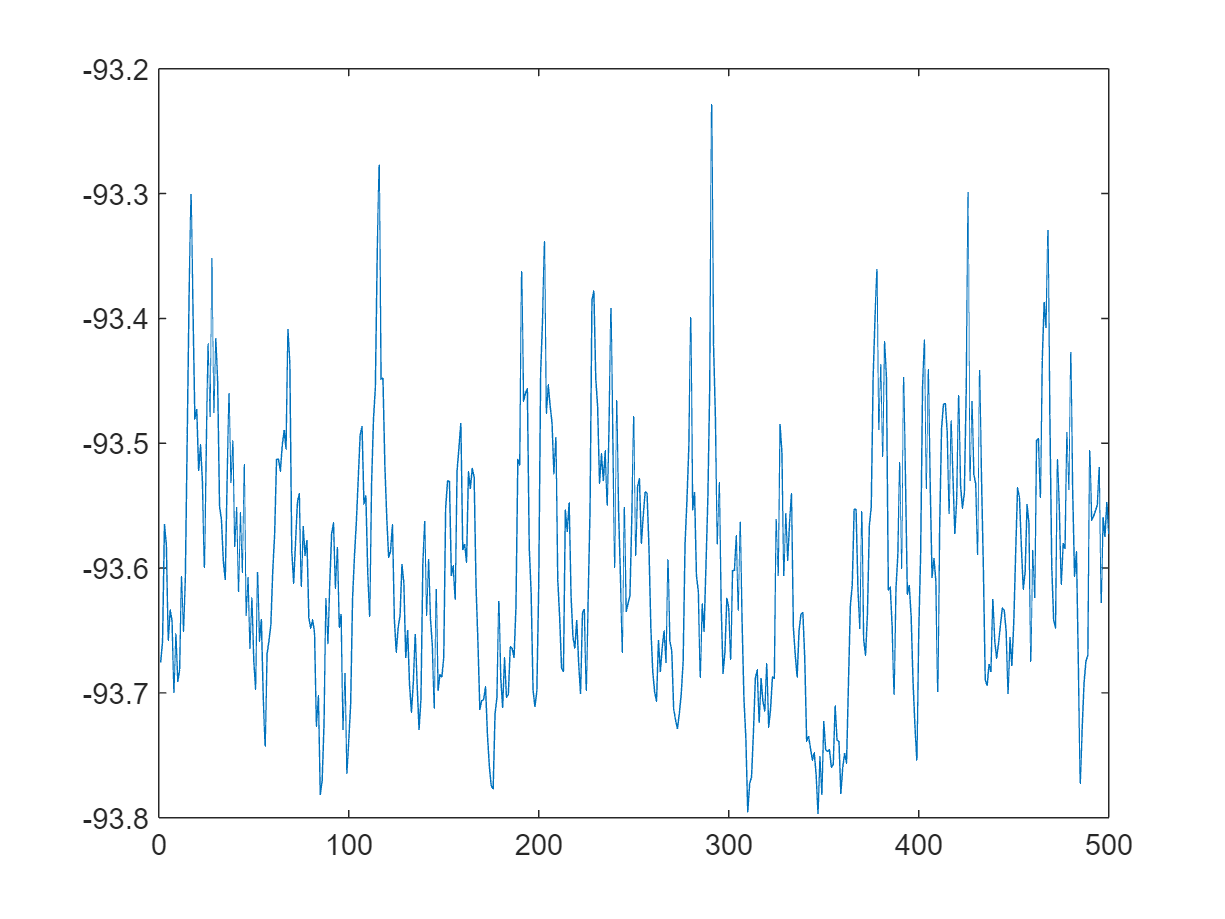

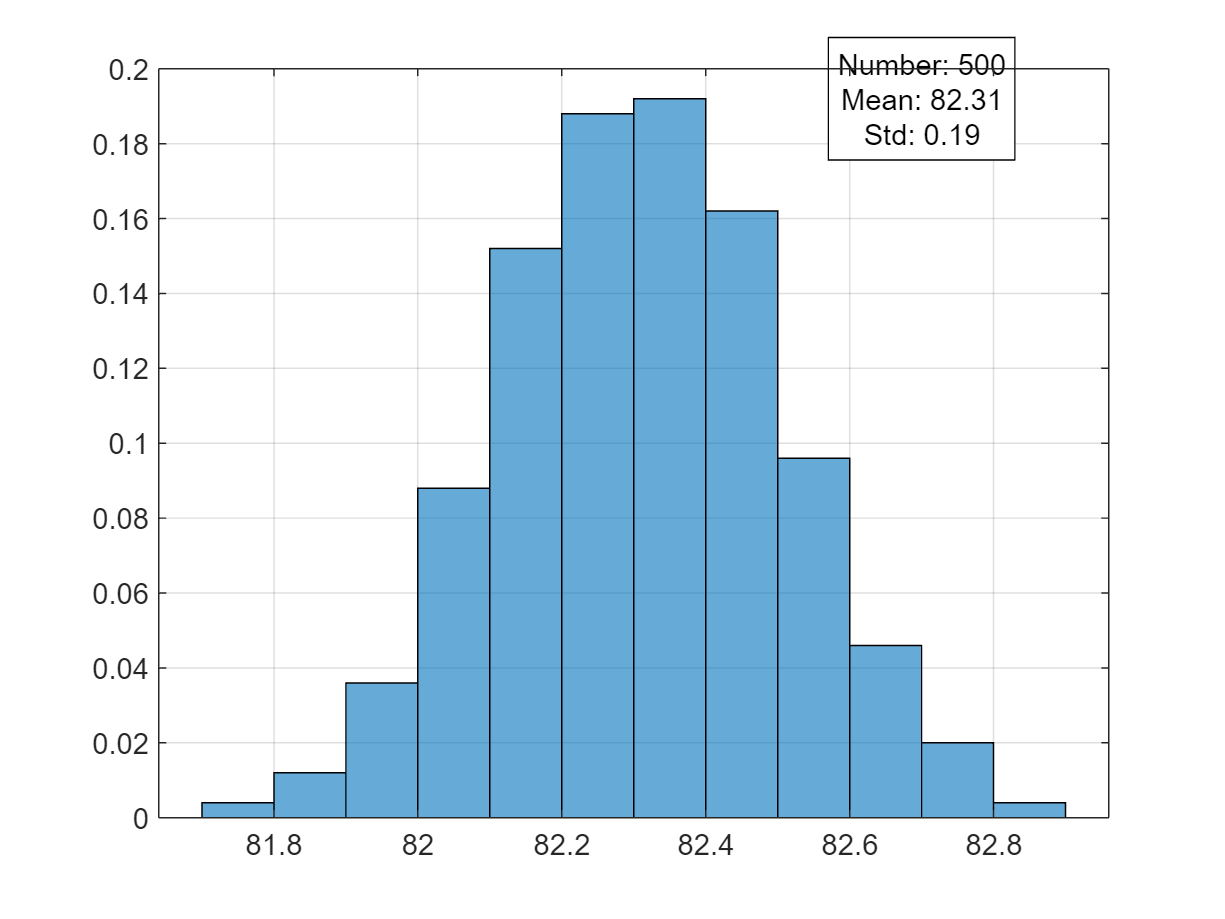

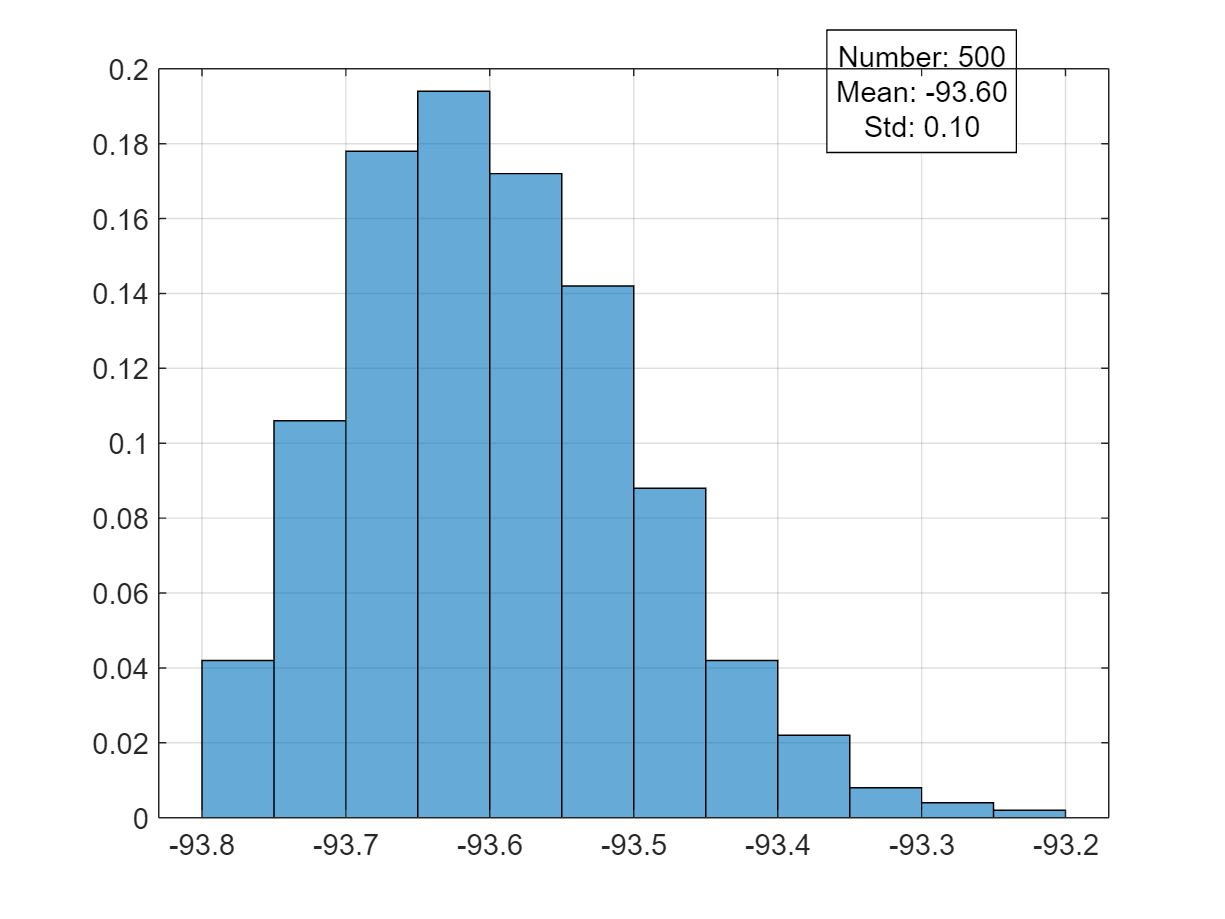

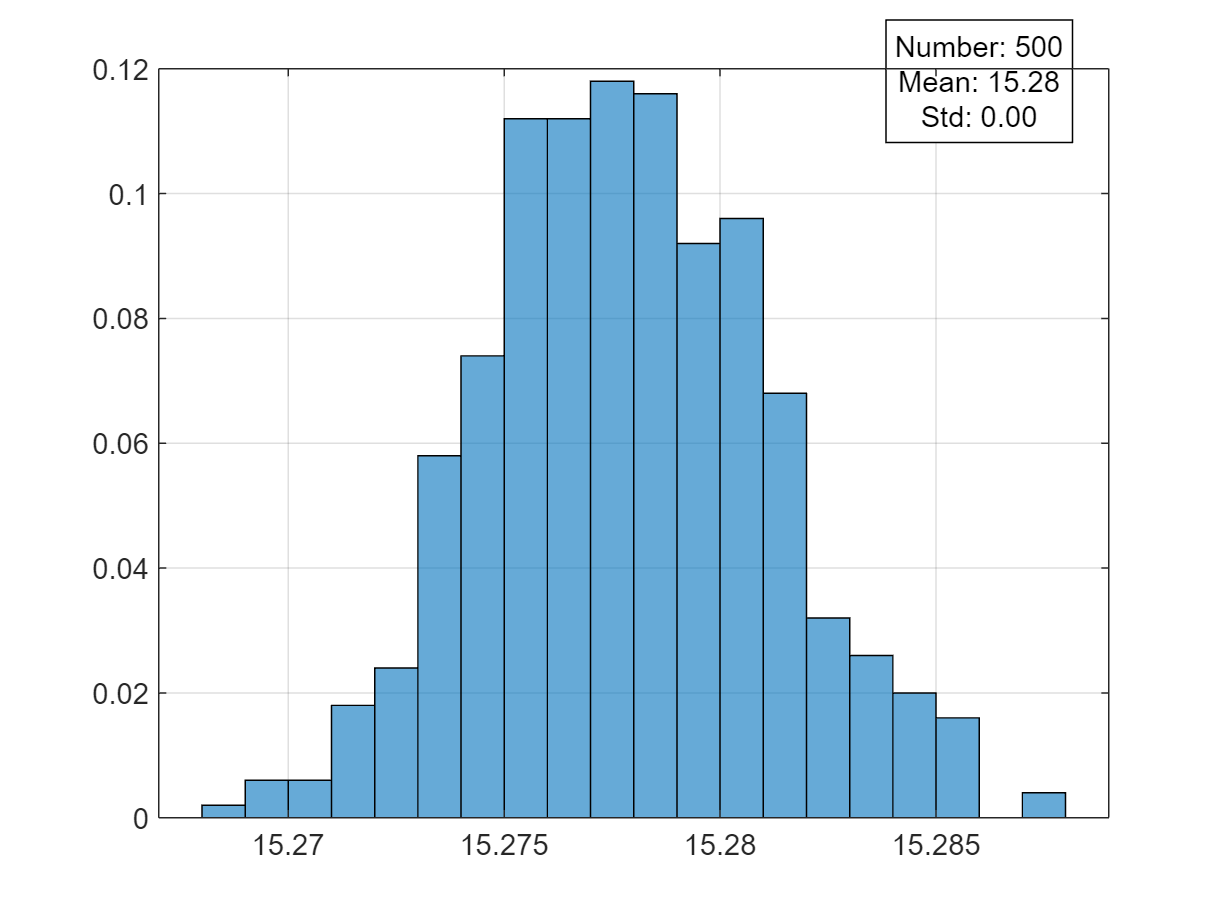

results = 包含以下字段的 struct :
    sinad_mean: 82.3109
     sinad_std: 0.1924
      thd_mean: -93.5967
       thd_std: 0.0990
     Gain_mean: 15.2778
      Gain_std: 0.0033
    sinad_list: [82.4549 82.4180 82.2355 82.2654 82.4160 82.3663 82.3840 82.5109 82.4053 82.4905 82.4677 82.3130 82.4018 82.3149 82.1109 81.9328 81.8195 81.9518 82.0904 82.0778 82.1596 82.1253 82.1759 82.2985 82.1306 81.9971 82.0876 81.8936 82.0824 … ]
      thd_list: [-93.6756 -93.6589 -93.5650 -93.5812 -93.6578 -93.6336 -93.6422 -93.6995 -93.6528 -93.6910 -93.6812 -93.6068 -93.6508 -93.6078 -93.4929 -93.3785 -93.3007 -93.3911 -93.4805 -93.4729 -93.5218 -93.5015 -93.5312 -93.5993 -93.5048 -93.4205 … ]


results = Calibration_statistics(Vout_N4, Gain_list, 50)

results

results = 包含以下字段的 struct :
    sinad_mean: 82.3728
     sinad_std: 0.3985
      thd_mean: -93.5972
       thd_std: 0.2092
     Gain_mean: 15.2792
      Gain_std: 0.0069
    sinad_list: [82.0551 82.6857 81.5915 82.4479 82.1902 82.5696 82.4479 82.9961 82.5696 82.5696 82.4479 82.4479 82.5696 82.3213 82.6857 82.3213 82.8995 82.4479 82.1902 81.9165 82.7959 82.9961 82.1902 82.8995 83.0851 82.3213 82.4479 82.5696 82.1902 … ]
      thd_list: [-93.4589 -93.7611 -93.1339 -93.6725 -93.5397 -93.7217 -93.6725 -93.8134 -93.7217 -93.7217 -93.6725 -93.6725 -93.7217 -93.6111 -93.7611 -93.6111 -93.8072 -93.6725 -93.5397 -93.3677 -93.7897 -93.8134 -93.5397 -93.8072 -93.8063 -93.6111 … ]


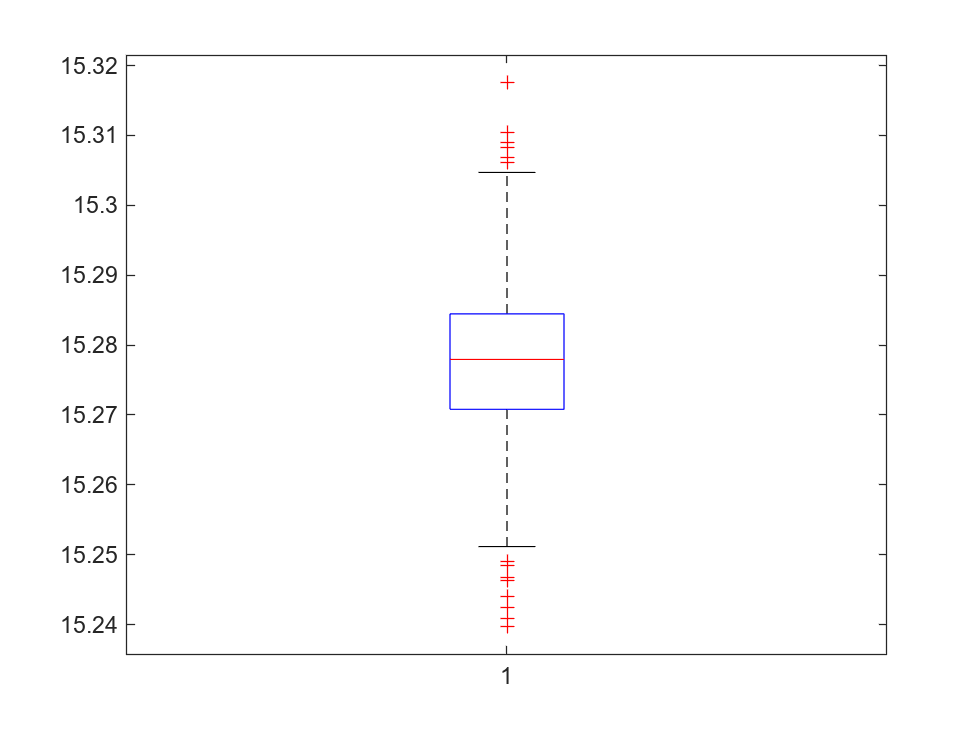

figure
boxplot(Gain_list)

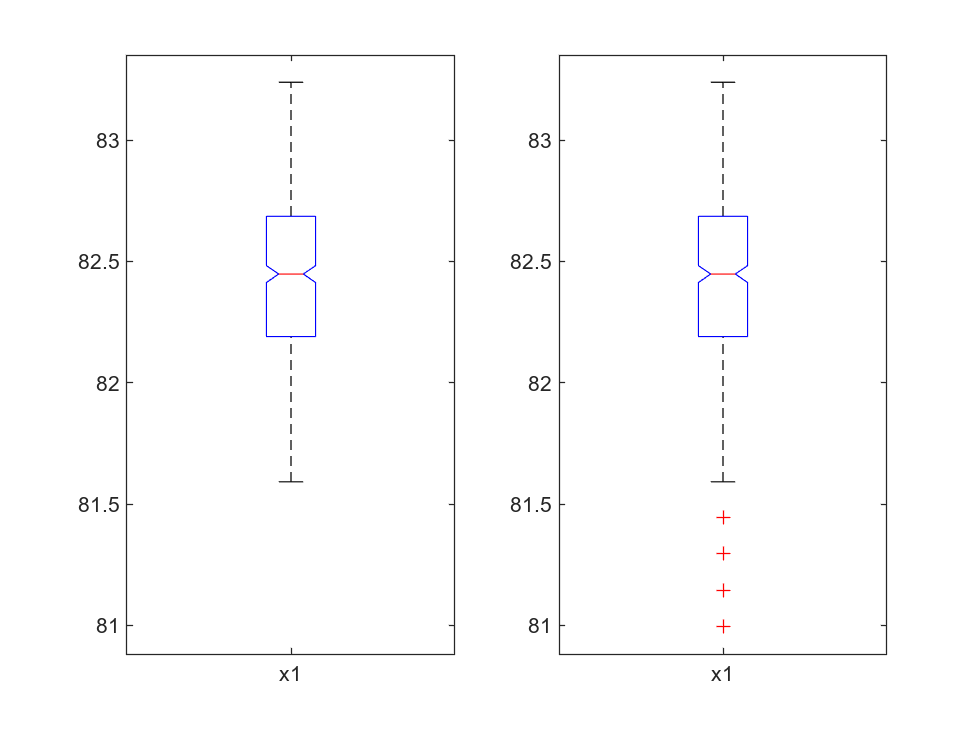

figure
subplot(1,2,1)
boxplot(results.sinad_list,'Notch','on', 'Symbol','', 'Labels','x1')
subplot(1,2,2)
boxplot(results.sinad_list,'Notch','on', 'Labels','x1')

figure("name",'boxplot')
data = [result_x1.sinad_list', result_x5.sinad_list', result_x10.sinad_list', result_x50.sinad_list', result_x100.sinad_list']

data =    82.0551   82.2094   82.4318   82.4549   82.4365
   82.6857   82.6398   82.4353   82.4180   82.2504
   81.5915   82.4972   82.6627   82.2355   82.3912
   82.4479   82.3723   82.2881   82.2654   82.4481
   82.1902   82.8169   82.4443   82.4160   82.4482
   82.5696   82.4970   82.5931   82.3663   82.3912
   82.4479   82.5456   82.4937   82.3840   82.3586
   82.9961   82.0125   82.3104   82.5109   82.0225
   82.5696   82.2358   82.2359   82.4053   81.8860
   82.5696   82.6398   82.4442   82.4905   82.0841


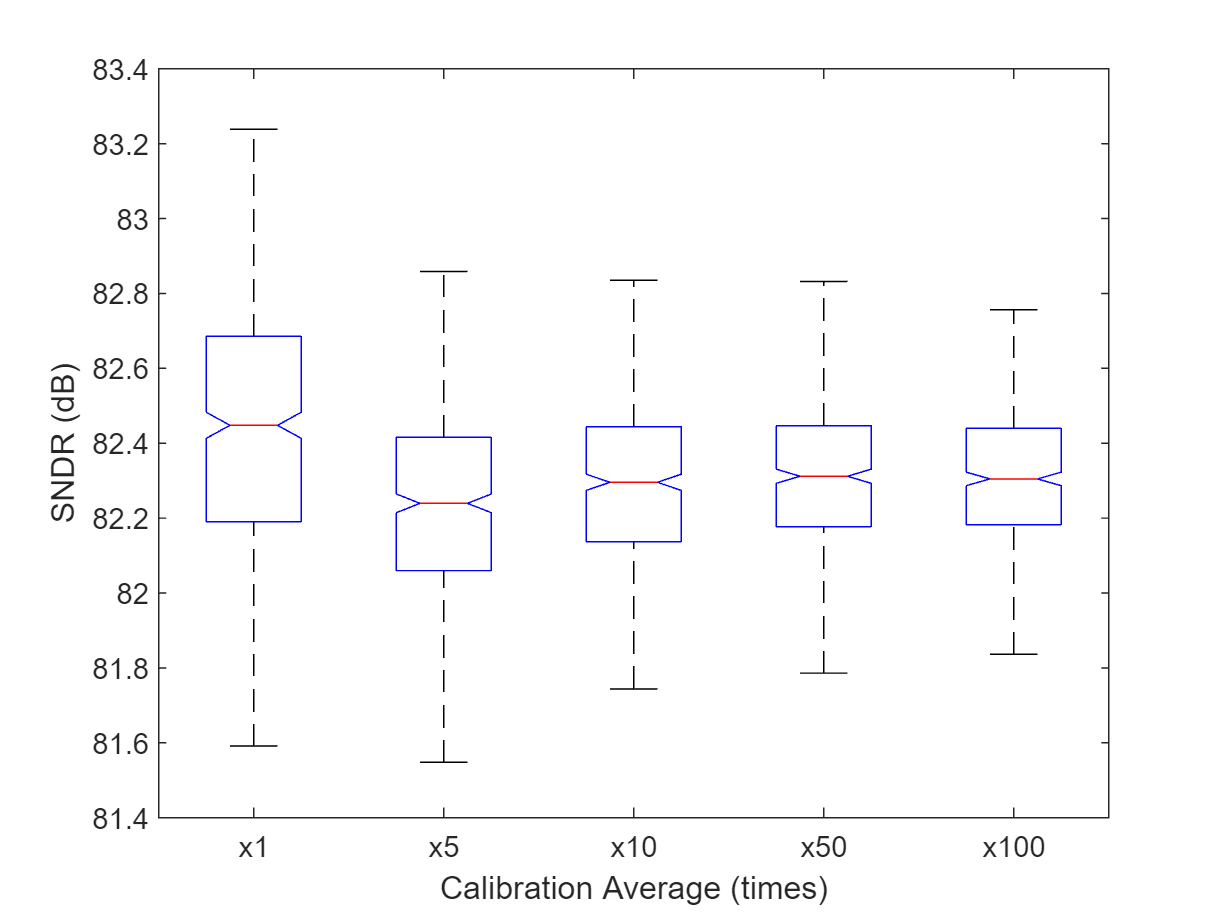

boxplot(data,'Notch','on','Symbol','', 'Labels',{'x1','x5','x10','x50','x100'})
ylabel("SNDR (dB)");
xlabel("Calibration Average (times)");
ylim([81.4 83.4])